%we want to solve 5 order polynomial coeffitients, given initial conditions.
% Martin: for report follow 31383 robotics project

t_in = 0;
t_out = 1;

%create symbolic matrix of n coeffitients
syms a0 a1 a2 a3 a4 a5
a = [a0 a1 a2 a3 a4 a5].'

$$a = \left(\begin{array}{c} a_{0}\\ a_{1}\\ a_{2}\\ a_{3}\\ a_{4}\\ a_{5} \end{array}\right)$$


Time_matrix = [ 1, t_in, t_in^2, t_in^3, t_in^4, t_in^5;
                0, 1, 2*t_in, 3*t_in^2, 4*t_in^3, 5*t_in^4;
                0, 0, 2, 6*t_in, 12*t_in^2, 20*t_in^3;
                1, t_out, t_out^2, t_out^3, t_out^4, t_out^5;
                0, 1, 2*t_out, 3*t_out^2, 4*t_out^3, 5*t_out^4;
                0, 0, 2, 6*t_out, 12*t_out^2, 20*t_out^3]

Time_matrix =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     2     0     0     0
     1     1     1     1     1     1
     0     1     2     3     4     5
     0     0     2     6    12    20



%initial conditions x(0) = [x0, x_dot0, x_ddot0, x1, x_dot1, x_ddot1] = [0, 0, 0, 1, 0, 0]
X0 = [0, 0, 0, 1, 0, 0].'

X0 =      0
     0
     0
     1
     0
     0



a = Time_matrix\X0

a =          0
         0
         0
   10.0000
  -15.0000
    6.0000


ex 5.2

clear
clc
close all
%%

%Cox-de Boor
T = [0,0,1,2,3,3,3]';
t = [];

for i = 1:(length(T)-1)
    temp = linspace(T(i),T(i+1), 101);
    t = [t, temp(1:(end-1))];
end

B01 = zeros(1,length(t));
for i = 1:length(B01)
    if t(i) >= 0 && t(i) < 1
        B01(i) = t(i);
    elseif t(i)>=1 && t(i) < 2
        B01(i) = 2-t(i);
    end
end

B11 = zeros(1,length(t));
for i = 1:length(B11)
    if t(i) >= 1 && t(i) < 2
        B11(i) = t(i)-1;
    elseif t(i)>=2 && t(i) < 3
        B11(i) = 3-t(i);
    end
end


B11 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


B01 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


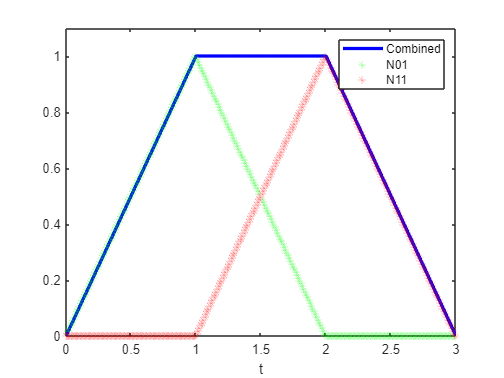


%% plot 
figure(1)
plot(t, B01+B11, 'b', 'LineWidth',2.5)
hold on
plot(t,B01, 'g*', 'LineWidth',0.1)
plot(t,B11, 'r*', 'LineWidth',0.1)
xlabel('t')
legend('Combined','N01', 'N11')
axis([0,3,0,1.1])
hold off